**Федеральное агентство железнодорожного транспорта**

Федеральное государственное бюджетное образовательное учреждение

высшего образования

«**Петербургский** **государственный университет путей сообщения Императора Александра ****I****»**

**(ФГБОУ ВО ПГУПС)**

­­­­­­­­­­­­––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––

Факультет «Транспортные и энергетические системы» 

Кафедра «Электрическая тяга»

**ОТЧЁТ**

**по лабораторной работе №4**

**«**Исследование мостового широтно-импульсного преобразователя с симметричным законом управления**»**

**Вариант №4**

Выполнили:

студенты гр. ПС-003 

Дулепов И.Г.

Минина А.С.

Проверил:

Сычугов А.Н.

Санкт-Петербург

2024

**1. Цель работы** - Исследование мостового широтно-импульсного преобразователя  (ШИП) с симметричным законом управления при работе на активно-индуктивную нагрузку с противо-э.д.с.

**2. Карткие теоретические сведения:**

Принципиальная схема широтно-импульсного преобразователя представлена на рисунке 1. Она содержит четыре транзисторных ключа VT1 –  VT4 с обратными диодами D1 – D4. В диагональ моста, образованного транзисторными ключами, включена нагрузка. Питание преобразователя осу ществляется от источника постоянного тока. 

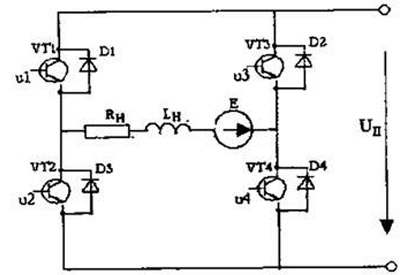

Рисунок 1. Принципиальная схема мостового широтно-импульсного преобразователя 

При симметричном способе управления в состоянии переключения  находятся все четыре транзисторных ключа моста, а напряжение на выходе  широтно-импульсного преобразователя представляет собой знакопеременные  импульсы, длительность которых регулируется входным сигналом. Управ ляющие импульсы поступают на пару диагонально расположенных транзи сторов VT1, VT4 или VT2, VT3.  Относительная продолжительность включения (величина, обратная  скважности) γ = τ/T, где τ – длительность управляющего импульса, Т – период повторения импульсов. 

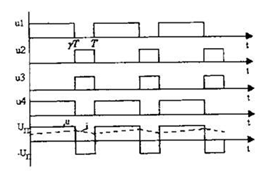

Рисунок 2 – Временные диаграммы преобразователя при симметричном управлении

На рисунке 3 приведена функциональная схема управления ШИП. Генератор пилообразного напряжения (ГПН), тактируемый генератором импульсов (Г), вырабатывает пилообразное напряжение с периодом Т. Схема сравнения (СС) представляет собой релейный элемент, который переключается с плюса на минус и обратно, в момент равенства напряжения с выхода  ГПН и напряжения на входе (рисунок 4). Для управления ШИП распределитель импульсов (РИ) имеет два выхода: один –прямой, второй – инверсный.  Эти импульсы, усиленные усилителями (У), поступают на базы диагонально расположенных пар транзисторов, переключая их в противофазе. 

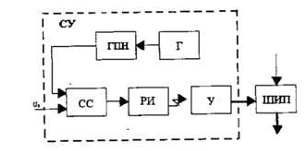

Рисунок 3 – Функциональная схема управления ШИП

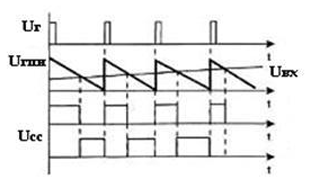

Рисунок 4 – Временные диаграммы работы схемы симметричного управления ШИП 

**3. Схема виртуальной установки:**

Виртуальная лабораторная установка для исследований, приведена на рисунке 5. 

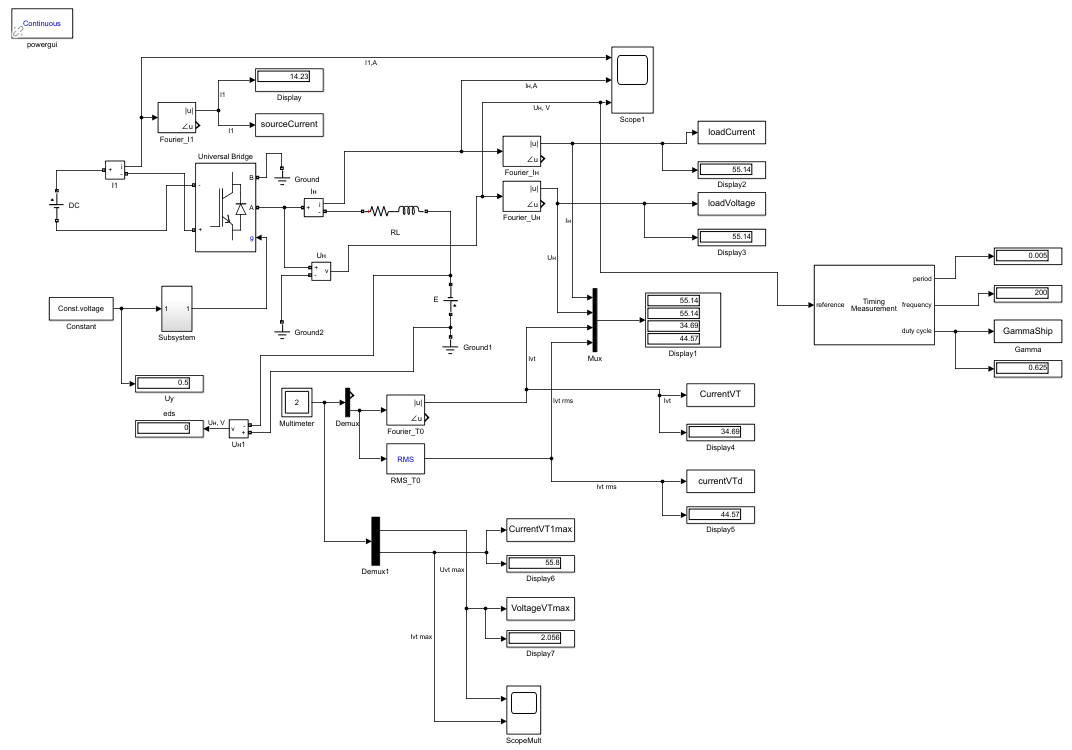

Рисунок 5 – Модель широтно-импульсного преобразователя в simulink

Модель блока управления (Subsystem) изображена на рисунке 6.

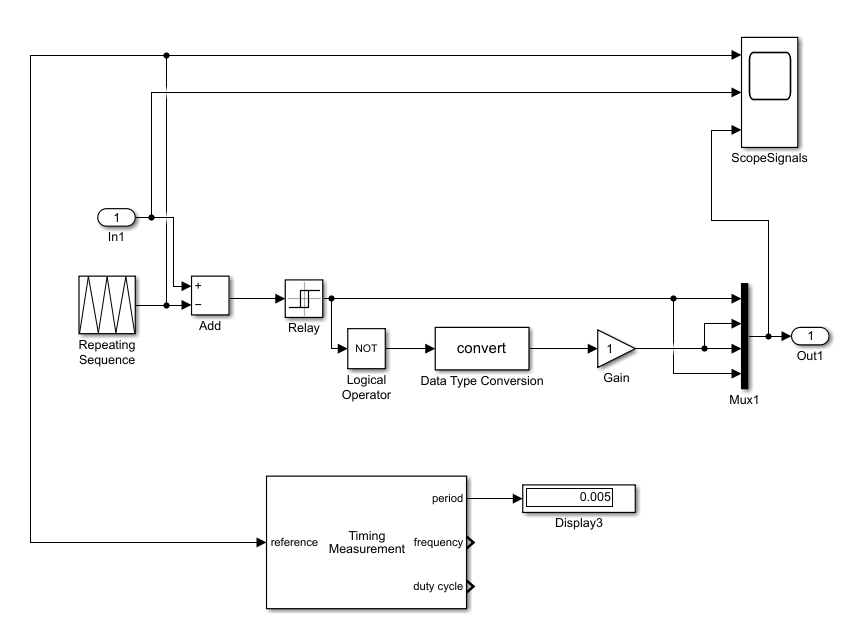

Рисунок 6 - Модель блока управления (Subsystem)

**4. Содержание работы:**

Исследование регулировочных и энергетических характеристик  мостового широтно-импульсного преобразователя (ШИП) с симметричным законом управления при работе на активно-индуктивную нагрузку с противо-э.д.с

**5. Задание исходных данных:**

Открываем файл с заданными параметрами:

open('Задание к ЛР4.txt')

Используем исходные данные, импортируемые из текстового файла задания:

C = readcell('Задание к ЛР4.txt');
ishoddan = C(4:11, 2:3);
data.Var = ishoddan{2,1};
data.Amplitude = ishoddan{4,2};
data.f = ishoddan{6,2};
data.R_n = ishoddan{8,2};
data.T = table(data.Var.',data.Amplitude.', data.f.', data.R_n.');
data.T.Properties.VariableNames = ["Вариант", "Amplitude, В","f, Гц","R_n, Ом"];
disp(data.T);

    Вариант    Amplitude, В    f, Гц    R_n, Ом
    _______    ____________    _____    _______

       4           225          200        1   



**Далее задаем в блоки модели Simulink:**

Параметры источника питания:

В поле настройки задаем величину напряжения Uп в вольтах (Amplitude,  V):

DCsource.Amplitude = data.Amplitude;

Параметры транзисторного ШИП:

В полях настойки задаем:

UB.SnubberRs = 1e5; % - параметры демпфирующих цепей (Snubber resistance, Snubber capacitance)
UB.SnubberCs = 1e-5;
UB.R_on = 1e-3; % динамическое сопротивление полупроводникового модуля открытом состоянии в Омах (Ron, Ohms )
UB.Vf = 2; %пороговое напряжение на транзисторе и диоде модуля в открытом состоянии в вольтах
UB.Vfd = 2;

Параметры нагрузки:

RL.Res = data.R_n; % устанавливаем значение активного сопротивления в Омах

Параметры индуктивности нагрузки выбираются так, чтобы постоянная  времени нагрузки находилась в пределах (2…5)Т (T=1/f , f - частота  источника), т.е LН=(2…5)* RН/f.

RL.Ind = (RL.Res/data.f)*3; % устанавливаем значение индуктивности в генри

Параметр блока э.д.с. нагрузки:

Eds.voltage = 0; %значение э.д.с. нагрузки, (0, 50, 100 В.)

Параметры блоков Fourier I1, Fourier I0, Fourier U0,  Fourier ТО:

В полях настройки устанавливаем частоту равную частоте напряжения ГПН (генератора пилообразного напряжения) и номер нулевой гармоники:

Fourier.frec = data.f;
Fourier.harmonic = 0;

Параметры ГПН (генератора пилообразного напряжения):

В полях настойки параметров ГПН задаем значения в соответствии с частотой  работы преобразователя в виде массива данных:

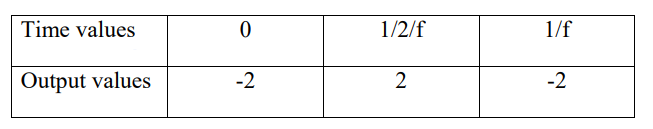

RepSec.Time = [0 1/2/data.f 1/data.f]; % период пилообразного напряжения
RepSec.Output = [-2 2 -2]; % амплитуда пилообразного напряжения

Параметры блока RMS Т (блока измерения действующего тока в  полупроводниковом модуле):

RMS_T.frec = data.f; %частота, на которой производится измерение

Параметр блока напряжения управления:

Const.voltage = -0.5; %напряжение управления, (от -1.9 В до 1.9 В.)

**6. Таблицы опытных и расчетных данных.**

Подготавливаем массивы для снятия параметров измерений в таблицу 1.

U_u = []; %Данные
E = [];
I_n = []; %Измерения
U_n = [];
I1 = [];
I_VT = [];
I_VT_RMS = [];
U_VT_max = [];
I_VT_max = [];
Gamma = []; %Вычисления
P_1 = [];
P_T = [];
P_n = [];

Открываем файл исследуемой модели:

%open('lr4_2022.slx')

При снятии характеристик параметры R, L нагрузки остаются без изменений, изменяется напряжение управления от -1.9 В до 1.9 В. Характеристики  снимаем для трех значений э.д.с. нагрузки 0, 50, 100 В.

Моделирование проводится для каждого значения напряжения управления и э.д.с.

Задаем шаг с которым будет изменятся: 

- значение напряжения управления Uу, В.:

UuStep=0.5; %значение шага Uу
Uumin_pred=-1.9; %предначальное значение Uу
Uumin=-1.5; %начальное значение Uу
Uumax_pred=1.5; %предконечное значение Uу
Uumax=1.9; %конечное значение Uу
U = [Uumin_pred Uumin:UuStep:Uumax_pred Uumax].';
UunumStep=height(U) %количество шагов Uу

UunumStep = 9

- значение э.д.с. нагрузки E, В.:

EStep=50; %значение шага э.д.с.
Emin=0; %начальное значение э.д.с.
Emax=100; %конечное значение э.д.с.
EnumStep=round((Emax-Emin)/EStep+1) %количество шагов э.д.с.

EnumStep = 3

Производим снятие характеристик:

for eds = Emin:EStep:Emax
    Eds.voltage = eds;
    E(end+UunumStep) = Eds.voltage;
    E = repelem(Emin:EStep:Emax,UunumStep);
    for Uu = U(1:1:end).' %end - до последнего значения в массиве U
    Const.voltage =  Uu;
    sim('lr4_2022.slx')
    U_u(end+1) = Const.voltage(end, 1);
    %I_n(end+1) = round(max(loadCurrent(end, 1)),2);
    %U_n(end+1) = round(max(loadVoltage(end, 1)),2);
    if Uu < 0
        I_n(end+1) = (round(min(loadCurrent(end, 1)),2))*(-1);
        U_n(end+1) = (round(min(loadVoltage(end, 1)),2))*(-1);
    else
       I_n(end+1) = round(max(loadCurrent(end, 1)),2);
       U_n(end+1) = round(max(loadVoltage(end, 1)),2);
    end
    I1(end+1) = round(max(sourceCurrent(end, 1)),2);
    I_VT(end+1) = round(max(CurrentVT(end, 1)),2);
    I_VT_RMS(end+1) = round(max(currentVTd(end, 1)),2);
    U_VT_max(end+1) = round(max(VoltageVTmax(end, 1)),2);
    I_VT_max(end+1) = round(max(CurrentVT1max(end, 1)),2);
    Gamma(end+1) = round(max(GammaShip(end, 1)),3);
    P_1(end+1) = round((DCsource.Amplitude)*(round(max(sourceCurrent(end, 1)),2)),2);
    P_T(end+1) = round((max(GammaShip(end, 1))*UB.Vf+(1-max(GammaShip(end, 1)))*UB.Vfd)*round(max(CurrentVT(end, 1)),2)+UB.R_on*((round(max(currentVTd(end, 1)),2))^2),2);
    P_n(end+1) = round(round(max(loadCurrent(end, 1)),2)*round(max(loadVoltage(end, 1)),2));
    end
end

Результаты моделирования и последующих вычислений заносим в таблицу 1.

Таблица 1 – Таблица измерений и вычислений

T1 = table(U_u.',E.',I_n.',U_n.',I1.',I_VT.',I_VT_RMS.',U_VT_max.',I_VT_max.',Gamma.',P_1.',P_T.',P_n.');
T1.Properties.VariableNames = ["Uу, В.","E, В.","I_n, А.","U_n, В.","I1, А.","I_VT, А.","I_VT_RMS, А.","U_VT_max, В.","I_VT_max, А.","Gamma","P_1, Вт.","P_T, Вт.","P_n, Вт."];
disp(T1);

    Uу, В.    E, В.    I_n, А.    U_n, В.    I1, А.    I_VT, А.    I_VT_RMS, А.    U_VT_max, В.    I_VT_max, А.    Gamma    P_1, Вт.    P_T, Вт.    P_n, Вт.
    ______    _____    _______    _______    ______    ________    ____________    ____________    ____________    _____    ________    ________    ________

     -1.9        0     -209.54    -209.53    199.05       5.24         33.16             223         -209.43       0.025      44786       11.58      43905  
     -1.5        0     -165.42    -165.42    124.16      20.63         58.38          

Относительную продолжительность импульса напряжения на нагрузке определяем по формуле:

где   T0 - период напряжения ГПН;

        время tи определяется по осциллограмме Load Voltage на оси абсцисс (т. е. при напряжении 0В).

При моделировании в симулинк, для нахождения относительной продолжительности импульса напряжения на нагрузке (коэффициента заполнения $\gamma$) воспользуемся блоком Timing Measurement, в параметрах настройки указываем duty cycle (рабочий цикл), значения выводим через блок simout в Workspace (рисунок 7):

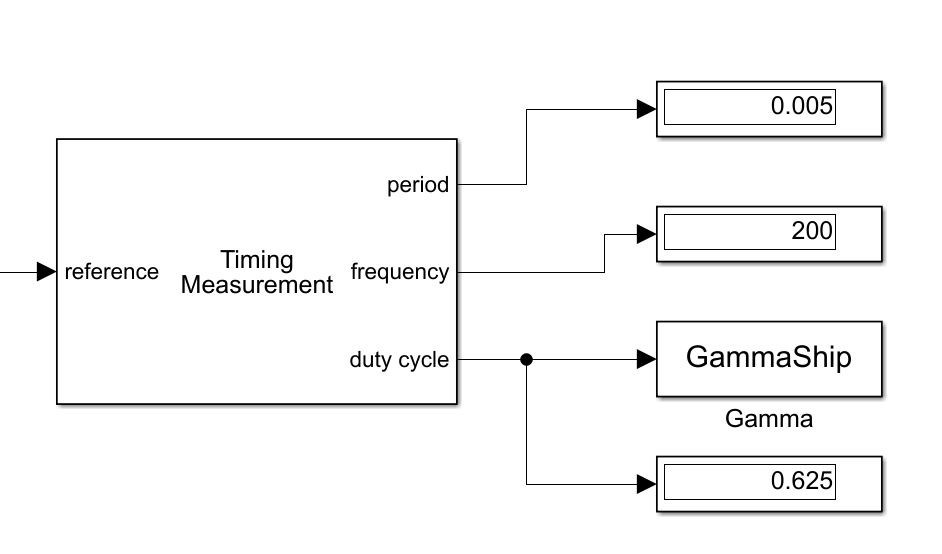

Рисунок 7. Блоком Timing Measurement для вывода значения $\gamma$ (относительной продолжительности импульса напряжения на нагрузке)

Также для достоверности используемых данных выводим через блок значения периода напряжения ГПН и частоты работы преобразователя.

Мощность в цепи источника питания рассчитываем по выражению: 

где Uп - напряжение питания. 

Квазистатические потери в силовом полупроводниковом модуле (ШИП) рассчитываем по уравнению:

где Vf ,Vfd , R0n ,- параметры силового модуля , а IVT, IVT(RMS)- его средний и действующий ток.

Мощность в нагрузке определяем по выражению:

**7. Регулировочные характеристики:**

Регулировочные характеристики зависимости напряжения нагрузки от значения коэффициента заполнения Uн = f($\gamma$) при трех заданных э.д.с. нагрузки приведены на графике ниже:

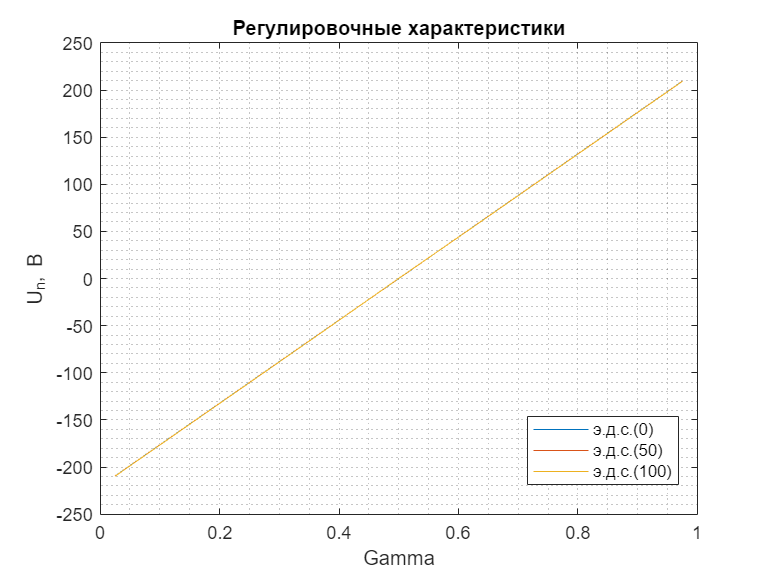

x1 = Gamma(1:9).';
y1 = U_n(1:9).';
x2 = Gamma(10:18).';
y2 = U_n(10:18).';
x3 = Gamma(19:27).';
y3 = U_n(19:27).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Gamma');
ylabel('U_n, В');
title('Регулировочные характеристики');
legend(["э.д.с.(0)","э.д.с.(50)","э.д.с.(100)"])
legend("Position",[0.69056,0.16136,0.18571,0.11905]);

**8. Энергетические характеристики:**

Энергетические характеристики зависимости тока питания от тока нагрузки ШИП I1 = f(Iн) при трех заданных э.д.с. нагрузки представлены ниже: 

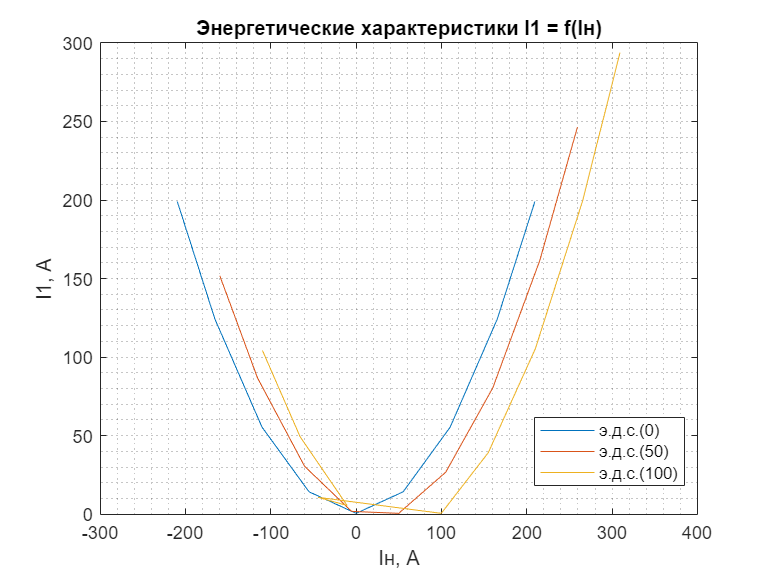

x1 = I_n(1:9).';
y1 = I1(1:9).';
x2 = I_n(10:18).';
y2 = I1(10:18).';
x3 = I_n(19:27).';
y3 = I1(19:27).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Iн, А');
ylabel('I1, А');
title('Энергетические характеристики I1 = f(Iн)');
legend(["э.д.с.(0)","э.д.с.(50)","э.д.с.(100)"])
legend("Position",[0.69836,0.15962,0.18571,0.11905]);

Энергетические характеристики зависимости тока силового транзистора от тока нагрузки ШИП IVT = f(Iн) при трех заданных э.д.с. нагрузки представлены ниже:

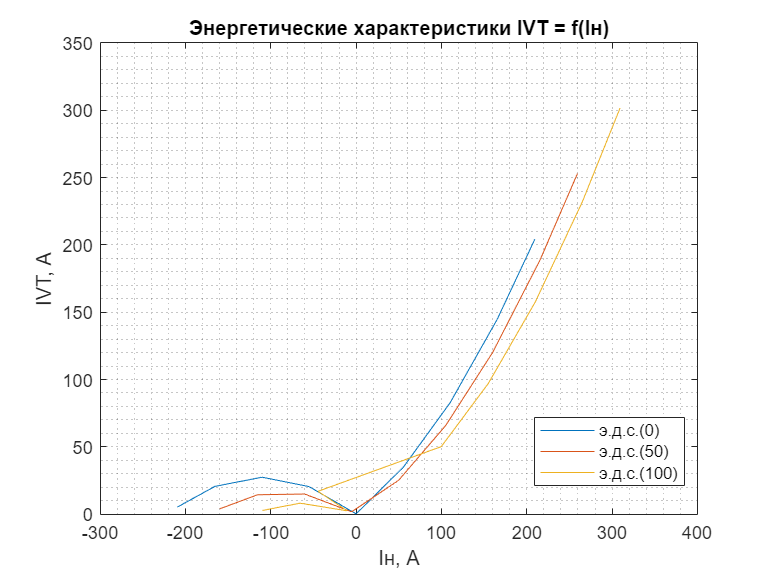

x1 = I_n(1:9).';
y1 = I_VT(1:9).';
x2 = I_n(10:18).';
y2 = I_VT(10:18).';
x3 = I_n(19:27).';
y3 = I_VT(19:27).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Iн, А');
ylabel('IVT, А');
title('Энергетические характеристики IVT = f(Iн)');
legend(["э.д.с.(0)","э.д.с.(50)","э.д.с.(100)"])
legend("Position",[0.69836,0.15962,0.18571,0.11905]);

Энергетические характеристики зависимости действующего тока силового транзистора от тока нагрузки ШИП IVT RMS= f(Iн) при трех заданных э.д.с. нагрузки представлены ниже:

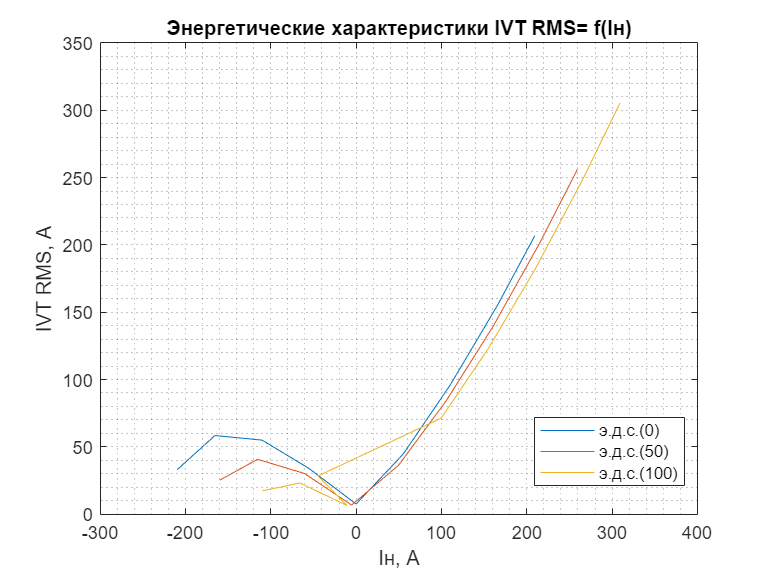

x1 = I_n(1:9).';
y1 = I_VT_RMS(1:9).';
x2 = I_n(10:18).';
y2 = I_VT_RMS(10:18).';
x3 = I_n(19:27).';
y3 = I_VT_RMS(19:27).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Iн, А');
ylabel('IVT RMS, А');
title('Энергетические характеристики IVT RMS= f(Iн)');
legend(["э.д.с.(0)","э.д.с.(50)","э.д.с.(100)"])
legend("Position",[0.69836,0.15962,0.18571,0.11905]);

Энергетические характеристики зависимости максимального тока силового транзистора от тока нагрузки ШИП IVT max = f(Iн) при трех заданных э.д.с. нагрузки представлены ниже:

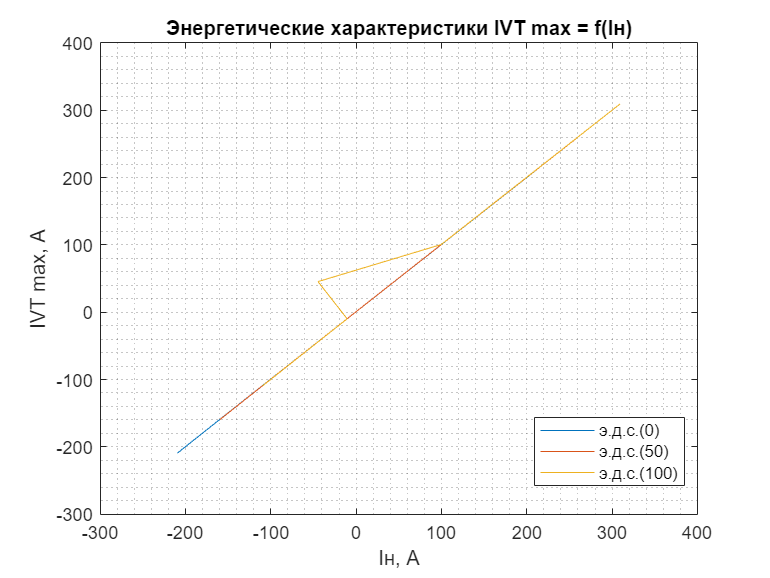

x1 = I_n(1:9).';
y1 = I_VT_max(1:9).';
x2 = I_n(10:18).';
y2 = I_VT_max(10:18).';
x3 = I_n(19:27).';
y3 = I_VT_max(19:27).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Iн, А');
ylabel('IVT max, А');
title('Энергетические характеристики IVT max = f(Iн)');
legend(["э.д.с.(0)","э.д.с.(50)","э.д.с.(100)"])
legend("Position",[0.69836,0.15962,0.18571,0.11905]);

Энергетические характеристики зависимости мощности в цепи источника питания от мощности в нагрузке ШИП P1 = f(Pн) при трех заданных э.д.с. нагрузки представлены ниже:

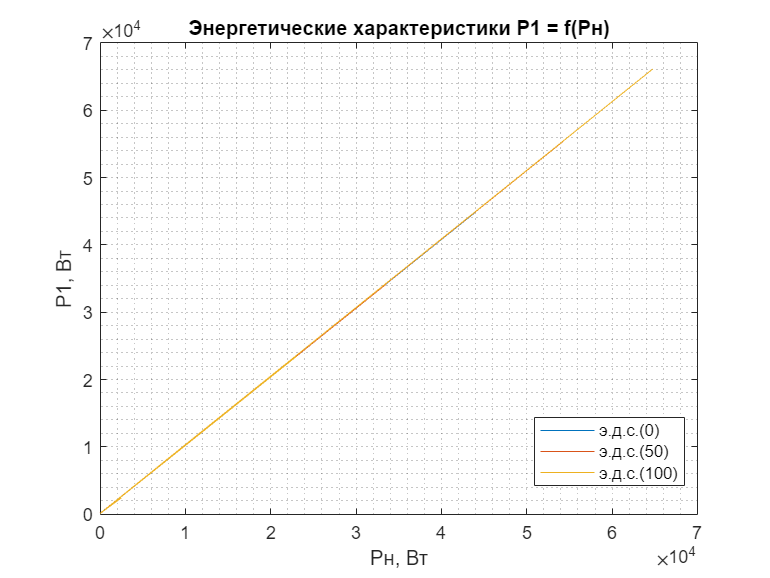

x1 = P_n(1:9).';
y1 = P_1(1:9).';
x2 = P_n(10:18).';
y2 = P_1(10:18).';
x3 = P_n(19:27).';
y3 = P_1(19:27).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Pн, Вт');
ylabel('P1, Вт');
title('Энергетические характеристики P1 = f(Pн)');
legend(["э.д.с.(0)","э.д.с.(50)","э.д.с.(100)"])
legend("Position",[0.69836,0.15962,0.18571,0.11905]);

Энергетические характеристики зависимости квазистатических потерь в ШИП от мощности в нагрузке ШИП Pт = f(Pн) при трех заданных э.д.с. нагрузки представлены ниже:

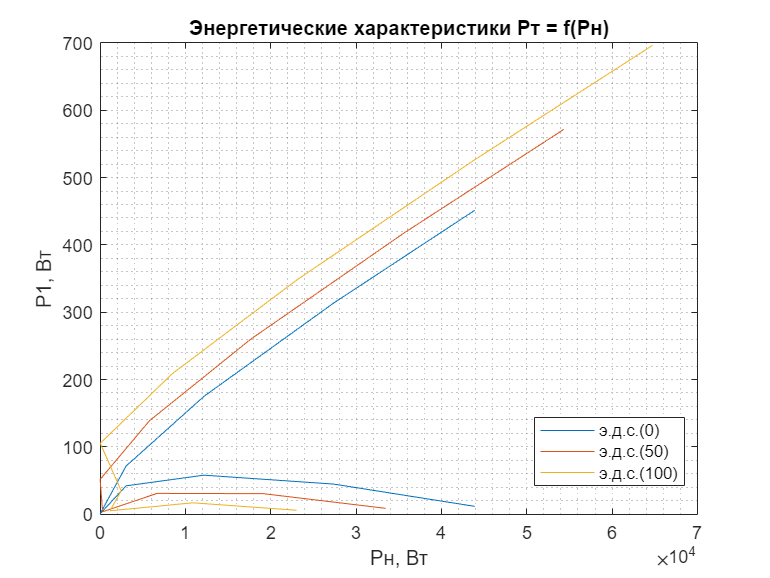

x1 = P_n(1:9).';
y1 = P_T(1:9).';
x2 = P_n(10:18).';
y2 = P_T(10:18).';
x3 = P_n(19:27).';
y3 = P_T(19:27).';
plot(x1,y1,x2,y2,x3,y3)
grid("minor");
xlabel('Pн, Вт');
ylabel('P1, Вт');
title('Энергетические характеристики Pт = f(Pн)');
legend(["э.д.с.(0)","э.д.с.(50)","э.д.с.(100)"])
legend("Position",[0.69836,0.15962,0.18571,0.11905]);

**9. Диаграммы тока питания, тока нагрузки и напряжения на нагрузке, тока и напряжения транзистора и диаграммы сигналов системы управления преобразователем (при напряжении управления Uу=0,5(-0.5) В, и противо-э.д.с. E=0 В):**

Масштаб построения осцилограмм по горизонали:

x.min = 0.2;
x.max = 0.21;

**9.1. При напряжении управления Uу = -0,5 В., и противо-э.д.с. E = 0 В.:**

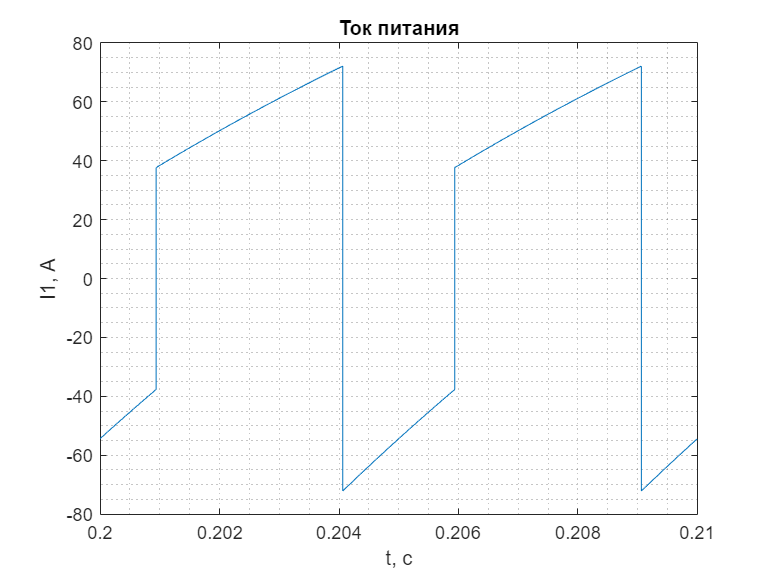

for eds = 0
    Eds.voltage = eds;
    Uu = -0.5;
    Const.voltage =  Uu;
    sim('lr4_2022.slx')
    U_u(end+1) = Const.voltage(end, 1);
end
    plot(Scope1{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('I1, А');
    title('Ток питания');
    xlim([x.min x.max]);

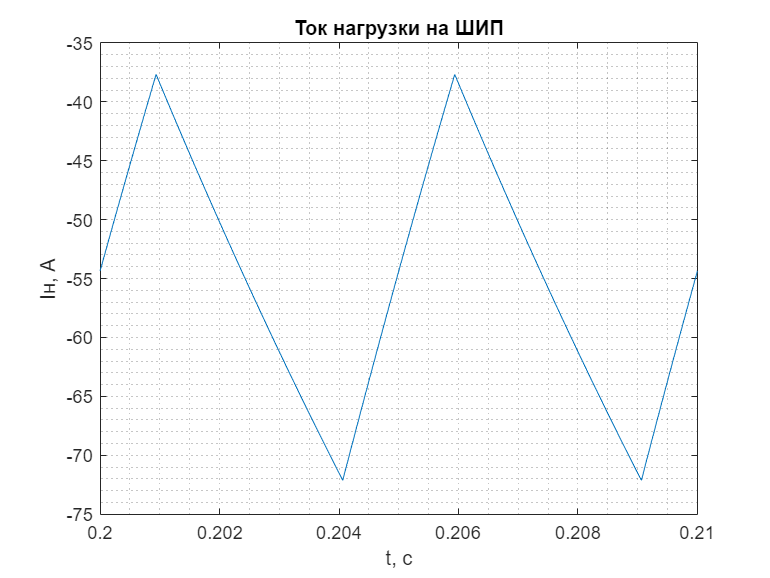

    plot(Scope1{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Iн, А');
    title('Ток нагрузки на ШИП');
    xlim([x.min x.max]);

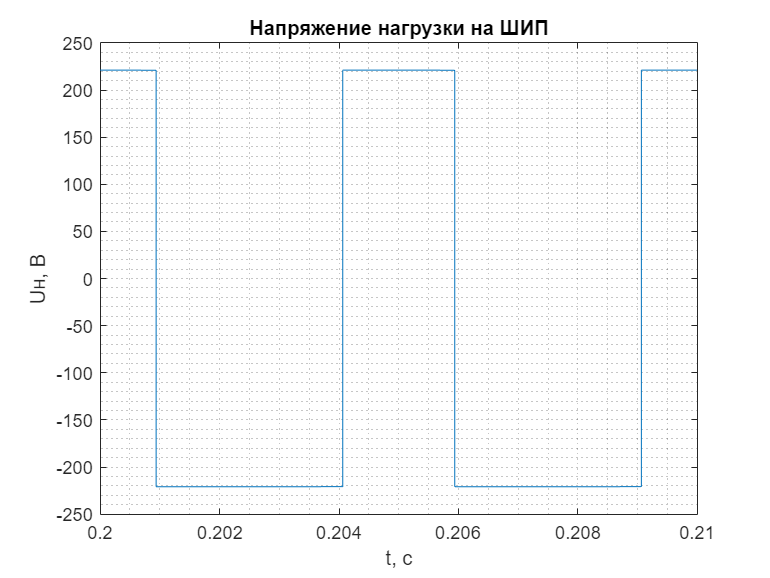

    plot(Scope1{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uн, В');
    title('Напряжение нагрузки на ШИП');
    xlim([x.min x.max]);

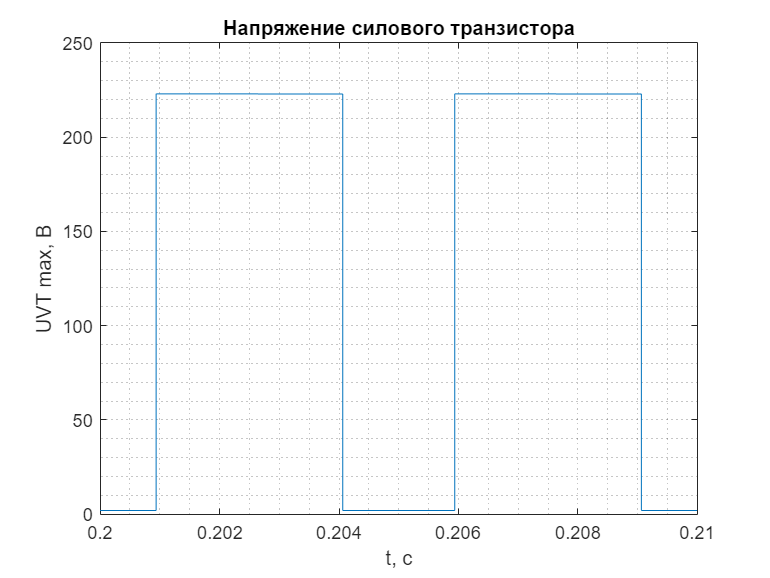

    plot(ScopeMult{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('UVT max, В');
    title('Напряжение силового транзистора');
    xlim([x.min x.max]);

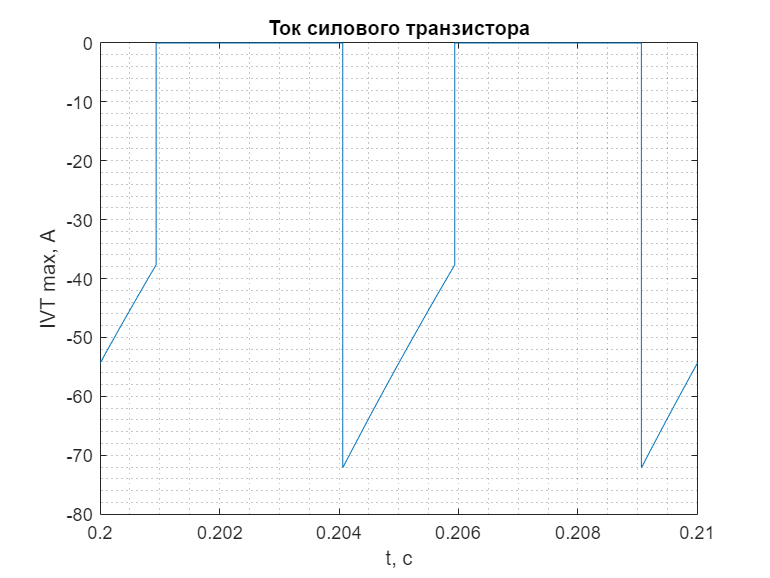

    plot(ScopeMult{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('IVT max, А');
    title('Ток силового транзистора');
    xlim([x.min x.max]);

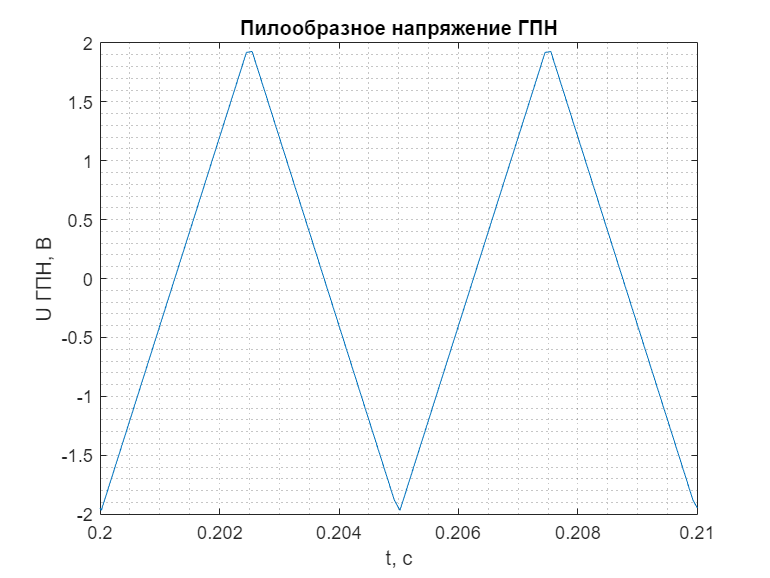

    plot(ScopeSignals{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('U ГПН, В');
    title('Пилообразное напряжение ГПН');
    xlim([x.min x.max]);

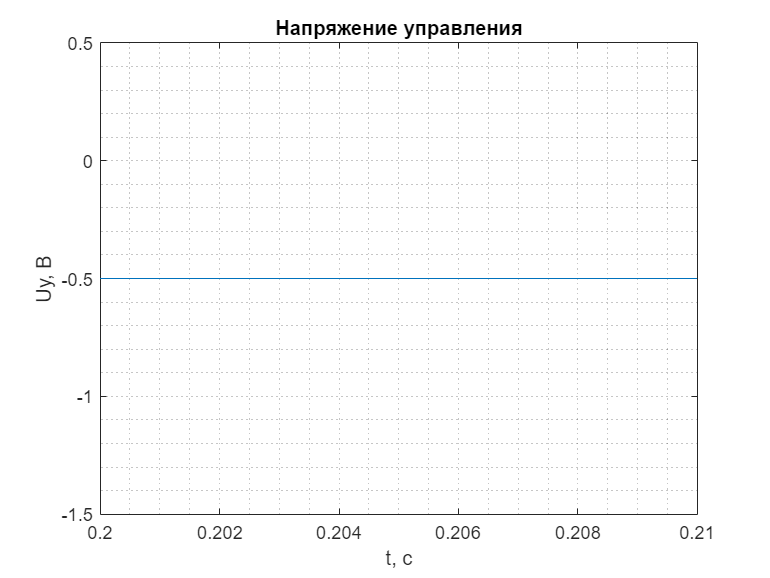

    plot(ScopeSignals{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uу, В');
    title('Напряжение управления');
    xlim([x.min x.max]);

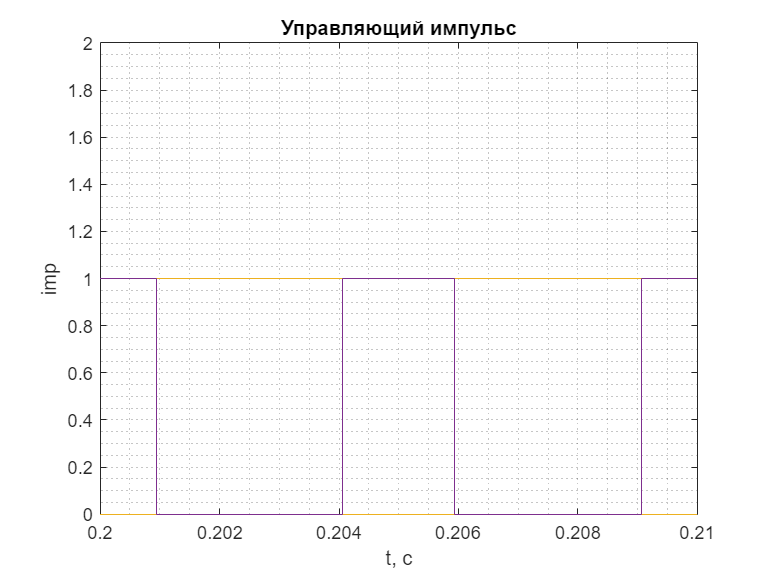

    plot(ScopeSignals{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющий импульс');
    xlim([x.min x.max]);
    ylim([0 2]);

**9.2. При напряжении управления Uу = 0,5 В., и противо-э.д.с. E = 0 В.:**

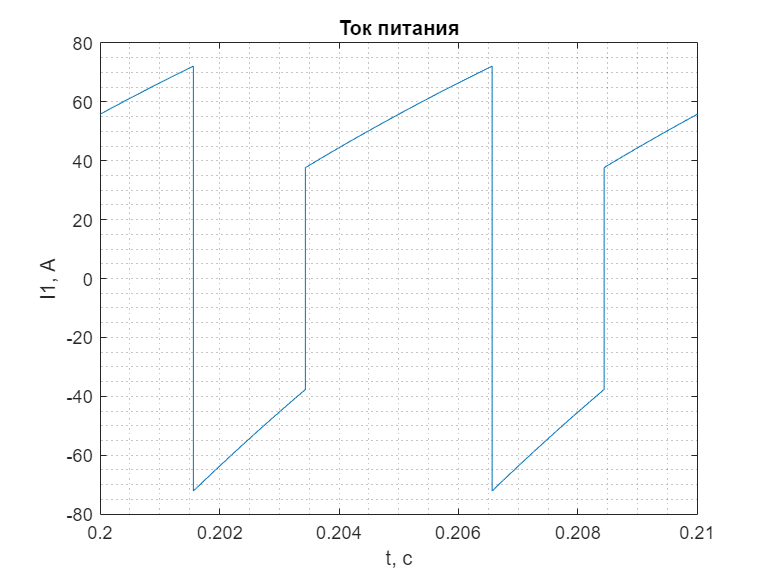

for eds = 0
    Eds.voltage = eds;
    Uu = 0.5;
    Const.voltage =  Uu;
    sim('lr4_2022.slx')
    U_u(end+1) = Const.voltage(end, 1);
end
    plot(Scope1{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('I1, А');
    title('Ток питания');
    xlim([x.min x.max]);

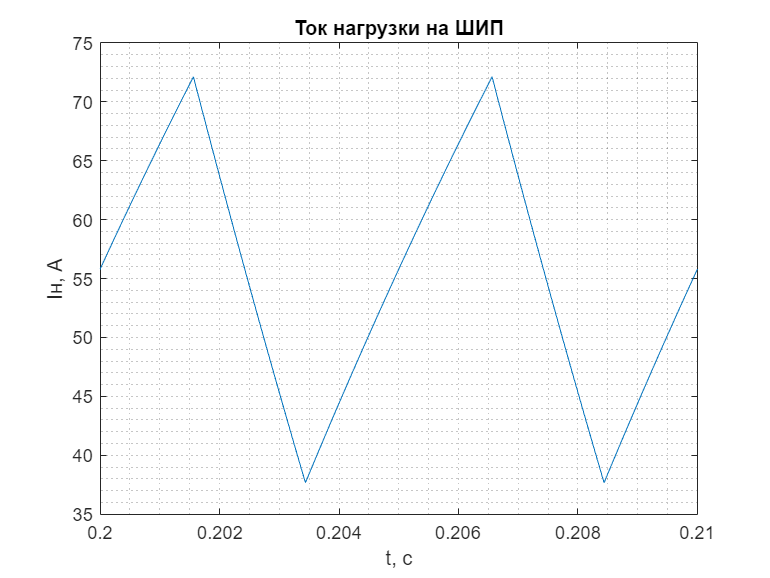

    plot(Scope1{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Iн, А');
    title('Ток нагрузки на ШИП');
    xlim([x.min x.max]);

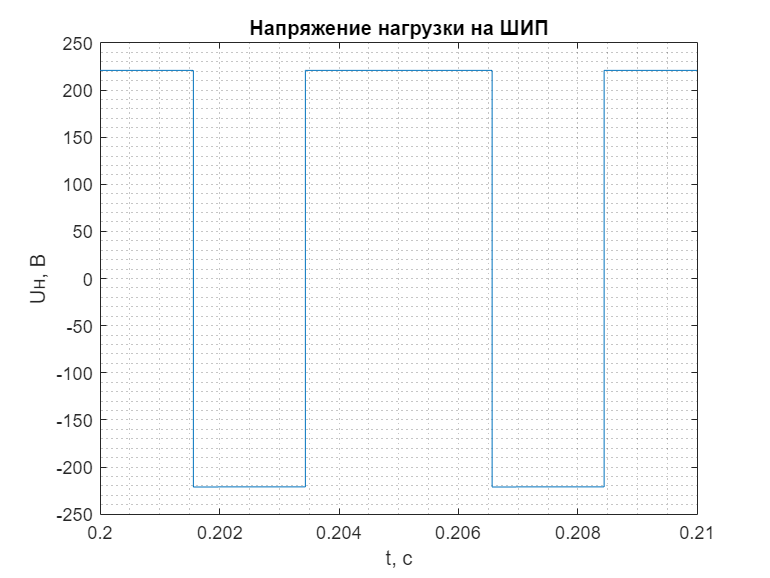

    plot(Scope1{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uн, В');
    title('Напряжение нагрузки на ШИП');
    xlim([x.min x.max]);

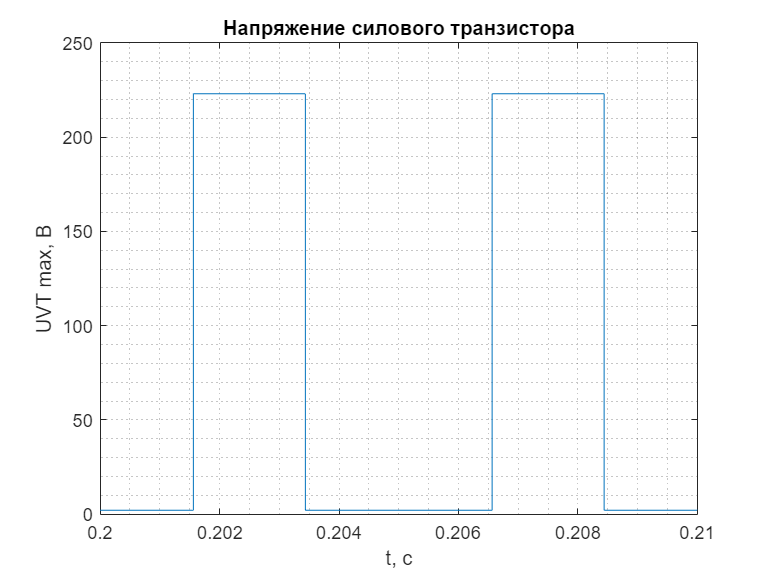

    plot(ScopeMult{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('UVT max, В');
    title('Напряжение силового транзистора');
    xlim([x.min x.max]);

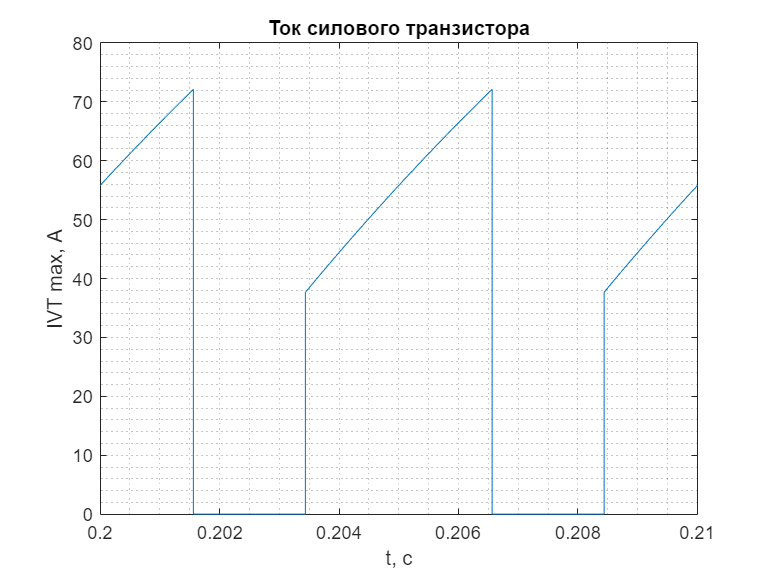

    plot(ScopeMult{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('IVT max, А');
    title('Ток силового транзистора');
    xlim([x.min x.max]);

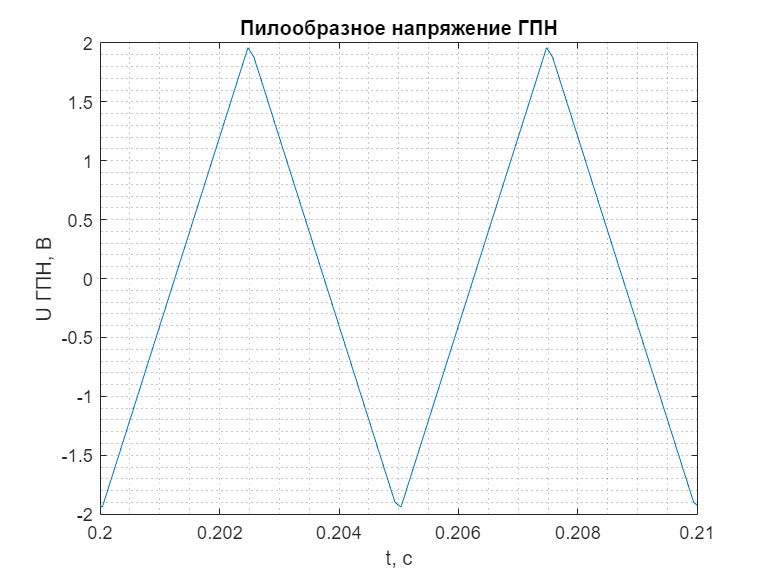

    plot(ScopeSignals{1}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('U ГПН, В');
    title('Пилообразное напряжение ГПН');
    xlim([x.min x.max]);

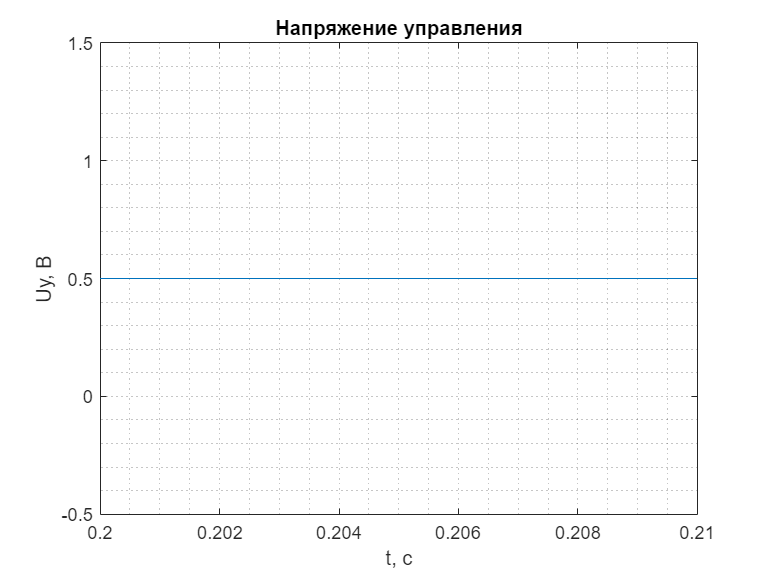

    plot(ScopeSignals{2}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('Uу, В');
    title('Напряжение управления');
    xlim([x.min x.max]);

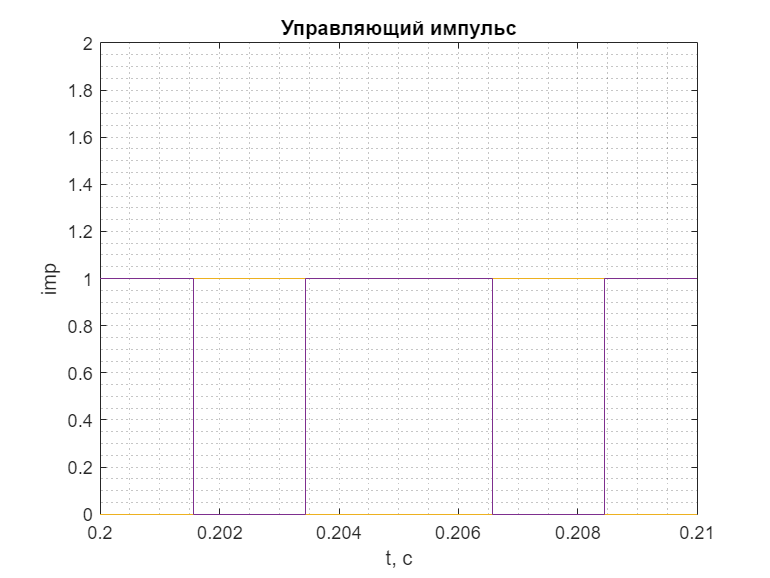

    plot(ScopeSignals{3}.Values);
    grid("minor")
    xlabel('t, с');
    ylabel('imp');
    title('Управляющий импульс');
    xlim([x.min x.max]);
    ylim([0 2]);

**10. Запись полученных данных в текстовый документ:**

Производим запись полученных в ходе выполнения лаборатоной работы таблицы измерений и вычислений: характеритик мостового широтно-импульсного преобразователя с симметричным законом управления:

writetable(T1,'Полученные в ходе расчета данные ЛР4.txt','WriteVariableNames',true,'Delimiter','tab');
type 'Полученные в ходе расчета данные ЛР4.txt';

Uу, В.	E, В.	I_n, А.	U_n, В.	I1, А.	I_VT, А.	I_VT_RMS, А.	U_VT_max, В.	I_VT_max, А.	Gamma	P_1, Вт.	P_T, Вт.	P_n, Вт.
-1.9	0	-209.54	-209.53	199.05	5.24	33.16	223	-209.43	0.025	44786.25	11.58	43905
-1.5	0	-165.42	-165.42	124.16	20.63	58.38	223	-165	0.125	27936	44.67	27364
-1	0	-110.28	-110.28	55.43	27.43	55	223.01	-109.61	0.25	12471.75	57.89	12162
-0.5	0	-55.14	-55.14	14.23	20.45	33.95	223.01	-54.36	0.375	3201.75	42.05	3040
0	0	0	0	0.51	0.25	7.51	223.02	0.77	0.5	114.75	0.56	0
0.5	0	55.14	55.14	14.23	34.69	44.57	223.07	55.8	0.625	3201.75	71.37	3040
1	0	110.28	110.28	55.43	82.85	95.92	223.12	110.76	0.75	12471.75	174.9	12162
1.5	0	165.42	165.42	124.16	144.79	154.85	223.17	165.67	0.875	27936	313.56	27364
1.9	0	209.53	209.53	199.06	204.3	206.9	223.21	209.58	0.975	44788.5	451.41	43903
-1.9	50	-159.64	-209.63	151.65	3.99	25.27	223	-159.53	0.025	34121.25	8.62	33465
-1.5	50	-115.52	-165.52	86.74	14.39	40.74	223.01	-115.1	0.125	19516.5	30.44	19121
-1	50	-60.38	-110.38	30.48	14.95	30.17	223.01	-59

open 'Полученные в ходе расчета данные ЛР4.txt' 

**Вывод:**

В ходе выполнения лабораторной работы было произведено исследование мостового широтно-импульсного преобразователя с симметричным законом управления. Выявлено, что:

- При увеличении напряжения управления Uу:  

1) Ток и напряжение нагрузки увеличиваются;  

2) Токи: I1, IVT, IVT RMS сначало уменьшаются до значения Uу = 0, а после начинают увеличиватся. При этом ток IVD MAX  увеличивается всегда;

3) Напряжение UVT max  при увеличения напряжения управления Uу не изменяется;  

4) Мощность источника питания P1, квазистатические потери в ШИП PT и мощность на нагрузке Pн уменьшаются до значения Uу = 0, а после начинают увеличиватся.

- При увеличении противо-э.д.с E: 

1) Значения всех токов при Uу < 0 уменьшаются, а при Uу < 0 увеличиваются; 

2) Мощности P1, PT и Pн аналогично значениям токов при  Uу < 0 уменьшаются, а при Uу < 0 увеличиваются;  

3) Напряжение на нагрузке и напряжение UVD max не изменяется.